# **Procesarea imaginilor - Detecția muchiilor și punctelor de interes**

# **Detecția muchiilor**

## **Notiuni generale**

- **accentuează **zonele de trecere de la o nuanță la alta (**muchii**) prin intermediul **operatorilor gradient**

- **** aplicarea acestor operatori pot duce la accentuarea zgomotului**

###     a. MUCHIA

- proprietate atașată fiecărui pixel

- caracterizată prin **modul** (**magnitudine**) și **direcție**

- **modului muchiei este același cu modulul gradientului, direcțiile sunt rotite cu 90 de grade**

- **profiluri tipice de muchii**

        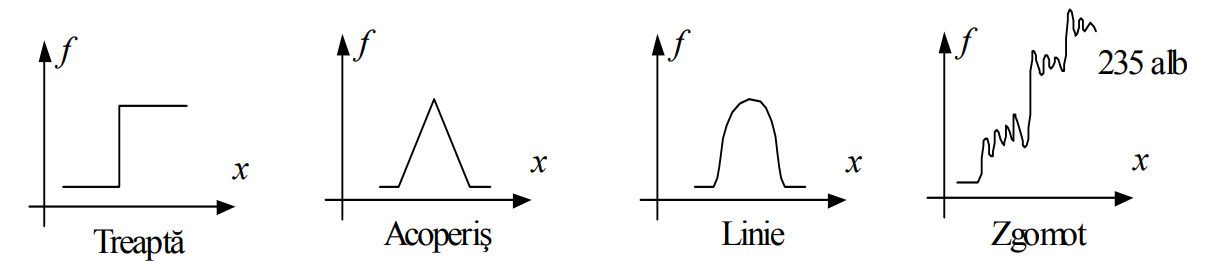

- operatorul **Laplacian** poate fi folosit pentru a calcula **modulul gradientului/muchiei**

        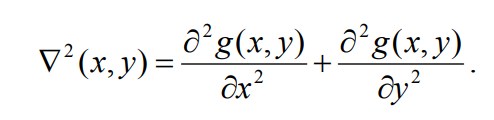

###     b. Operatorii Gradient

#### Operatorul Roberts

- puține calcule, dar sensibilitate crescută la zgomot

% două măști de convoluție
h1 = [ 1  0; ...
       0 -1]
h2 = [ 0 1; ...
      -1 0]

% magnitudinea muchiei
% m = abs( g(i, j) - g(i+1, j+1) ) + abs( g(i, j+1) - g(i+1, j) )

#### Operatorul Prewitt

% două măști de convoluție
hx = [ -1 0 1; ...
       -1 0 1; ...
       -1 0 1]
hy = [ -1 -1 -1; ...
        0  0  0; ...
        1  1  1]

#### Operatorul Sobel

% două măști de convoluție
hx = [ -1 0 1; ...
       -2 0 2; ...
       -1 0 1]
hy = [ -1 -2 -1; ...
        0  0  0; ...
        1  2  1]

#### Operatorul Laplacian

- exprimă cea de-a doua derivată

- aproximat prin sumă de convoluție cu o mască de 3x3

h1 = [ 0  1 0; ...
       1 -4 1; ...
       0  1 0]
h2 = [ 1  1 1; ...
       1 -8 1; ...
       1  1 1]    

### **c**. Matlab functions

### edge

- **detectează muchiile folosind diverși operatori cunoscuți**

- **see *****help***

### imfilter

- **filtrarea** imaginii și **modificarea dimensiunii **acesteia prin intermediul unei **metode de interpolare **

- **see *****help***

### **conv2**

- ** convoluție bidimensională**

- **see *****help***

### ** imnoise**

- **adaugă zgomot **unei imagini

- **see ***** help*** 

## Exercitiul 1

- **Citiți** imaginea **"L6_image_01.tif"**

- **Aplicați operatorul gradient** **Prewitt** pe **axa X**, apoi pe **axa Y** (***imfilter***)

- La final aplicați **operatorul Prewitt **folosind ***edge***

- **Afișați rezultatele **folsind ***subplot *****(imagine initiala, muchii x, muchii y, edge)**

% Prewitt - două măști de convoluție
hx = [ -1 0 1; ...
       -1 0 1; ...
       -1 0 1]
hy = [ -1 -1 -1; ...
        0  0  0; ...
        1  1  1]

## Exercitiul 2

- **Citiți** imaginea **"coins.png"**

- Aplicați, în ordine, **operatorii Roberts**, **Prewitt**, **Sobel**, **Log** și **Canny**  folosind ***edge****, *salvând imaginile obținute în **variabile separate**

- **Afișați rezultatele **folsind ***subplot *****(imagine initiala, edges pentru fiecare operator folosit)**

## Exercitiul 3

- **Citiți** imaginile **"L6_image_01.tif" **și "**coins.png**"

- Aplicați, **la alegere**, pe baza exercițiului anterior, unul dintre operatorii, folosind **edge (apelata cu 3 argumente)**

- **Evidențiati muchiile obținute, suprapunându-le peste imaginea inițială, prin intermediul culorii roșii**

**    => **exemplu vizual de cum ar arăta rezultatele dorite:

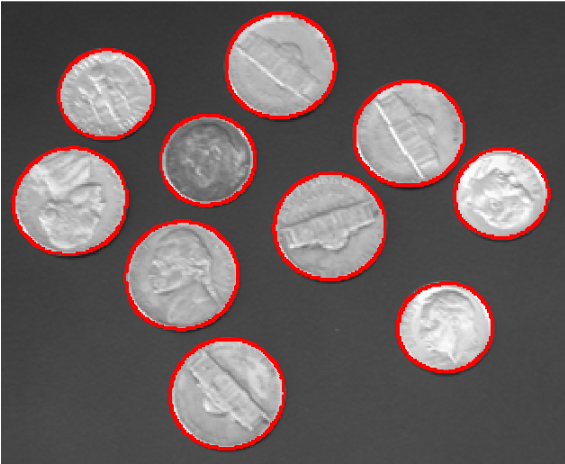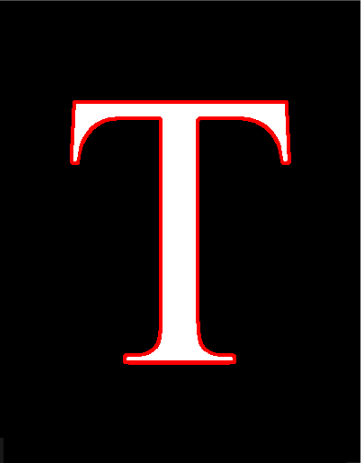

## Exercitiul 4

- **Citiți** imaginea **"L6_image_01.tif"**

- **Aplicați zgomot de tip ***salt and peper ***pe aceasta imagine **folosind ***imnoise*** 

- Încercați detecția muchiilor pe imagina cu zgomot

- **Afișați rezultatele **folsind ***subplot ***

# **Detectarea punctelor de interes**

- **Concept folosit pentru a urmări traiectora de mișcare a unui obiect în timp captat în diferite imagini**

- **Algoritmi: Interest Point Operator, Smith și Harris.**

- **IPO: variația intensității pixelolor pe 4 axe**

- **Smith: criteriu geometric**

- **Harris: calcul al primei derivate alături de funcția de autocorelație**

### **IPO**

### 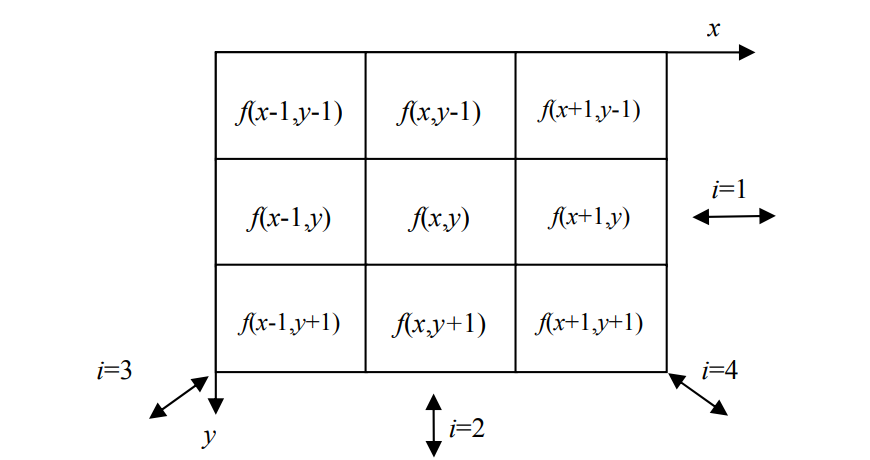

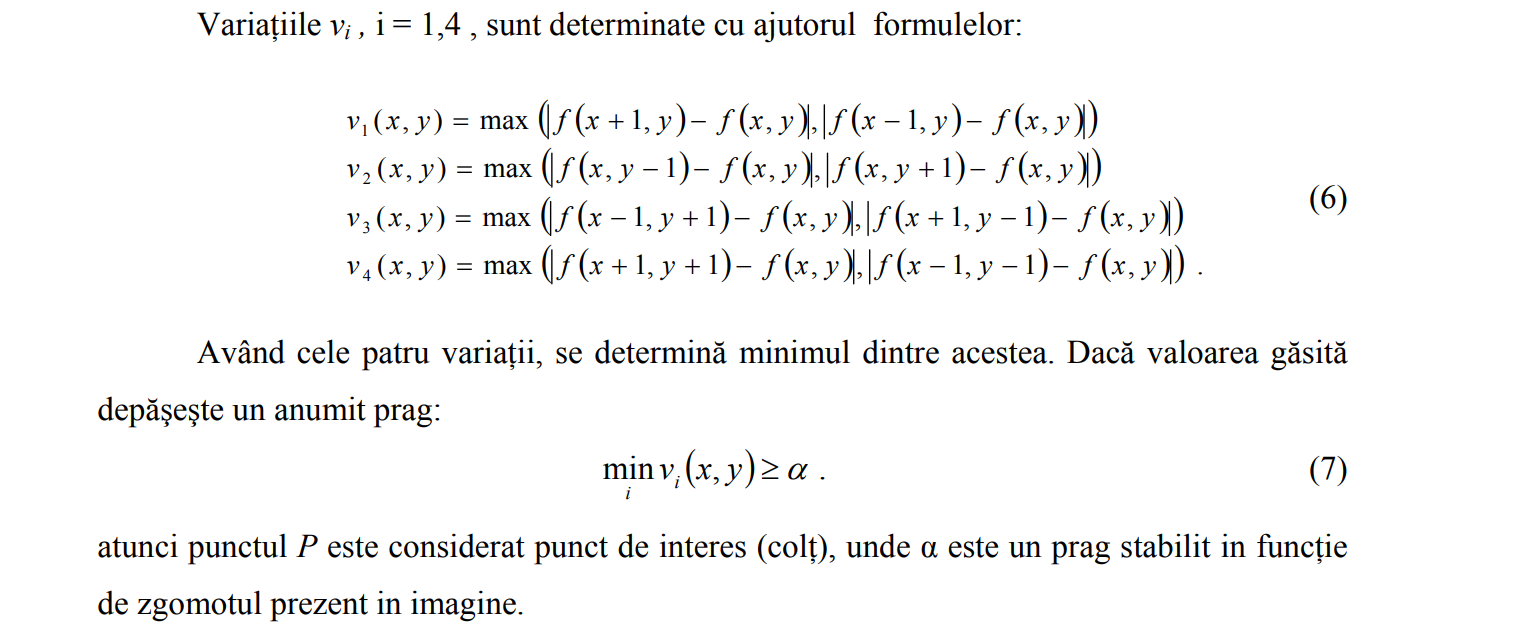

## Exercitiul 1

- **Citiți** imaginea **"L6_image_02.tif"**

- **Implementați algoritmul de IPO (Interest Point Operator)**

- **Afișați rezultatele suprapuse peste imaginea inițială**

**    => **exemplu vizual de cum ar arăta rezultatele dorite:

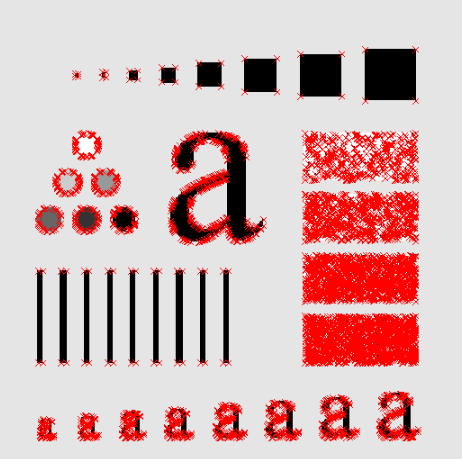

% cum sa nu folositi for
[m, n] = size(img); % unde img reprezinta imaginea citita de voi
x = 2:m-1;
y = 2:n-1;

## Exercitiul 2

- **Citiți** imaginea **"L6_image_01.tif"**

- **Apelând **funcția ***detectMinEigenFeatures*****, **determinați** cele mai importante 10 colțuri (**verificati ce** returneaza *****detectMinEigenFeatures***** + *****selectStrongest*****() )**

- **Afișați **rezultatele folosind** subplot**

**    => **exemplu vizual de cum ar arăta rezultatele dorite: